# Simulate Building Energy Management System

Copyright 2024 The MathWorks, Inc.

In this workflow, you learn how to parameterize and prepare a model for detailed Building Management System (BMS) simulations. The end of the workflow results in a parameterized model for you to review and run based on your requirements. This example demonstrates how to set up and use the model with various room HVAC configurations: `Room Radiator Only,` `Room Underfloor Heating/Cooling Only`, or `Room Radiator with Underfloor Heating/Cooling`. You will learn how to size radiators or underfloor piping differently for each room, control fluid valves for rooms, and calculate actual power consumption in the system under realistic load conditions.

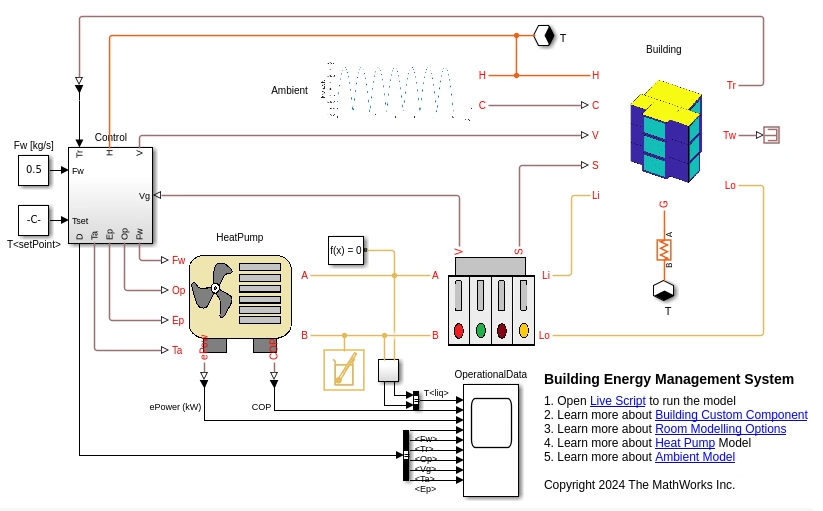

This picture illustrates the basic setup you will use in this example. The **Building** component is connected to the **Ambient** and the **HeatPump** components through the **OperationalData** block. The bundle of Simscape thermal liquid nodes from the building connects to a single thermal liquid node at the **OperationalData** block. The **Control** subsystem models the opening or closing of room valves based on operational parameters and other measurements. You can use this model as a starting point to develop your network and analyze actual energy consumption.

## Read Building Data

Load the building data with solar load from the `building_with_solar_load` XML file.

[apartment3D, geoLocation, dateTimeVec] = ...
    readBuildingDataXML(FileName="building_with_solar_load.xml");

    {'Location:Bengaluru'}

Simulation Duration:
*** Start Time :01-May-2024 01:00:00
*** End Time   :07-May-2024 01:00:00
*** Room Names in Building : Bathroom,Kitchen,Bedroom,LivingRoom


Set viewing direction for all 3D plots.

viewingAngle = [-1 -1 1]; 

Plot the building walls and roof, and create an icon for the building custom model in Simscape.

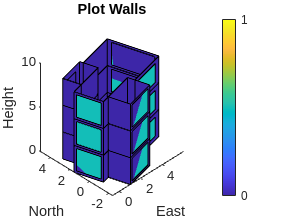

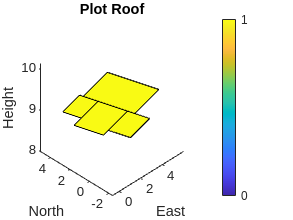

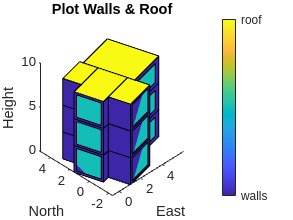

plotBuildingWallsAndRoof(Building=apartment3D,...
                         PlotViewDirection=viewingAngle);

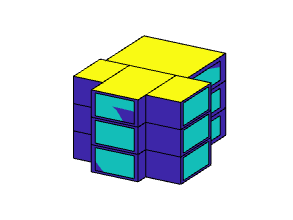

createIconBuildingCustomComponent(Building=apartment3D,...
                                  PlotViewDirection=viewingAngle);

## Update HVAC Model

By default, all rooms have the same configuration:

- **Radiator**: The radiator front area is set in comparison to the largest wall in the room. The default configuration specifies that the radiator spans 25% of the largest wall area.

- **Underfloor Piping**: The underfloor piping coverage is specified in comparison to the room's floor. The default setting covers 100% of the floor area, which means that the underfloor piping extends across the entire floor area.

For all floor levels, adjust the underfloor piping area to cover 50%  of the total floor area for the Kitchen and Bathroom only.

buildingDataStruct = ...
    editHVACModelParameterRoom(Building=apartment3D,...
                               ListOfLevels=(1:3)',...
                               ListOfRooms=["Kitchen";"Bathroom"],...
                               ModelParameter="Underfloor Coverage Area Fraction",...
                               NewValue=0.9);

## Set Operational Parameters

Initialize building room physics data.

physTable = initializeRoomOperationalPhysicsData(Building=buildingDataStruct,...
                                                 Duration=dateTimeVec);
hoursTracked = hour(dateTimeVec(1:end));
disp(strcat("Number of hours of simulation = ",num2str(length(hoursTracked))));

Number of hours of simulation = 145


Add room occupancy data for the simulation duration. 

- For certain specified datetime values, as defined by dateTimeVec([1:3,15:end]), set the room occupancy level for each *Bedroom* on the 2nd floor of the building as 2.

    physTable = editParametersForBuildingPhysics(PhysicsTable=physTable,...
                                                 ListOfLevels=2,...
                                                 ListOfRooms="Bedroom",...
                                                 ListOfTimeValues=dateTimeVec([1:3,15:end])',...
                                                 PhysicsParameter="Room Occupancy Level",...
                                                 NewValue=2);

For all the given Room List & DateTimeVector, Room Occupancy Level = 2
 
Updated Physics Table:
 
       Date and Time        Level    Apartment    Room     Room Name      HVAC On    Heat Source (W)    Electrical Load (W)    Room Occupancy Level
    ____________________    _____    _________    ____    ____________    _______    _______________    ___________________    ____________________

    01-May-2024 01:00:00      1          1         1      "LivingRoom"     true             0                    0                      0          
    01-May-2024 01:00:00      1          1         2      "Bedroom"        true             0                    0                      0          
   

- For certain specified datetime values, as defined by dateTimeVec(14), set the room occupancy level for each *Kitchen* on the 3rd floor of the building as 2.

    physTable = editParametersForBuildingPhysics(PhysicsTable=physTable,...
                                                 ListOfLevels=1,...
                                                 ListOfRooms="LivingRoom",...
                                                 ListOfTimeValues=dateTimeVec(4:6)',...
                                                 PhysicsParameter="Room Occupancy Level",...
                                                 NewValue=1);

For all the given Room List & DateTimeVector, Room Occupancy Level = 1
 
Updated Physics Table:
 
       Date and Time        Level    Apartment    Room     Room Name      HVAC On    Heat Source (W)    Electrical Load (W)    Room Occupancy Level
    ____________________    _____    _________    ____    ____________    _______    _______________    ___________________    ____________________

    01-May-2024 01:00:00      1          1         1      "LivingRoom"     true             0                    0                      0          
    01-May-2024 01:00:00      1          1         2      "Bedroom"        true             0                    0                      0          
   

- For certain specified datetime values, as defined by dateTimeVec(4:6), set the room occupancy level for each *LivingRoom* on the 1st floor of the building as 1.

    physTable = editParametersForBuildingPhysics(PhysicsTable=physTable,...
                                                 ListOfLevels=3,...
                                                 ListOfRooms="Kitchen",...
                                                 ListOfTimeValues=dateTimeVec(14)',...
                                                 PhysicsParameter="Room Occupancy Level",...
                                                 NewValue=2);

For all the given Room List & DateTimeVector, Room Occupancy Level = 2
 
Updated Physics Table:
 
       Date and Time        Level    Apartment    Room     Room Name      HVAC On    Heat Source (W)    Electrical Load (W)    Room Occupancy Level
    ____________________    _____    _________    ____    ____________    _______    _______________    ___________________    ____________________

    01-May-2024 01:00:00      1          1         1      "LivingRoom"     true             0                    0                      0          
    01-May-2024 01:00:00      1          1         2      "Bedroom"        true             0                    0                      0          
   

- Switch off HVAC when not needed. For all building floors from 1st till the 3rd and datetime specified by dateTimeVec(7:13), switch of the HVAC requirement for all rooms, the *BedRoom*, the *LivingRoom*, the *Kitchen*, and the *Bathroom*.

    physTable = editParametersForBuildingPhysics(PhysicsTable=physTable,...
                                                 ListOfLevels=(1:3)',...
                                                 ListOfRooms=["Bedroom"; "LivingRoom"; "Kitchen"; "Bathroom"],...
                                                 ListOfTimeValues=dateTimeVec(7:13),...
                                                 PhysicsParameter="HVAC On",...
                                                 NewValue=false);

For all the given Room List & DateTimeVector, HVAC On = 0
 
Updated Physics Table:
 
       Date and Time        Level    Apartment    Room     Room Name      HVAC On    Heat Source (W)    Electrical Load (W)    Room Occupancy Level
    ____________________    _____    _________    ____    ____________    _______    _______________    ___________________    ____________________

    01-May-2024 01:00:00      1          1         1      "LivingRoom"     true             0                    0                      0          
    01-May-2024 01:00:00      1          1         2      "Bedroom"        true             0                    0                      0          
    01-May-2024 

## Parameterize Model

### Ambient Custom Block

Get the parameters for sunrise time, sunset time, and a list of days for the simulation from the `buildingDataStruct` struct generated from the XML above.

[opsParams.listOfDays,...
    opsParams.simStartTime,...
    opsParams.sunrise,...
    opsParams.sunset] = ...
    getAmbientTemperatureVariationModelData(DateTimeVector=dateTimeVec,...
                                            Location=geoLocation);

Specify the average day-time temperatures, average night-time temperatures, and the percentage variation from these averages during both day and night. Provide the day and night average temperatures for all days, as outlined in the building data XML part file.

opsParams.averageDayTvec   = 303*ones(1,length(opsParams.listOfDays));
opsParams.averageNightTvec = 299*ones(1,length(opsParams.listOfDays));
opsParams.percentDayTvar   = 1;
opsParams.percentNightTvar = 1;

Set desired temperature operating point for the building rooms.

opsParams.desiredTempSetPoint = 295;

Estimate initial ambient temperature based on simulation start time.

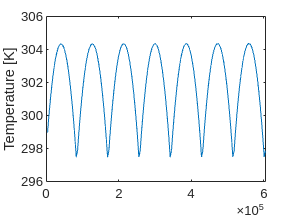

[t,Tamb] = createIconAmbientCustomComponent(AvgDayTemperatureVec=opsParams.averageDayTvec,...
                                            PercentDayTemperatureVar=opsParams.percentDayTvar,...
                                            AvgNightTemperatureVec=opsParams.averageNightTvec,...
                                            PercentNightTemperatureVar=opsParams.percentNightTvar,...
                                            SunriseVec=opsParams.sunrise,...
                                            SunsetVec=opsParams.sunset);

opsParams.initialTemperature = round(interp1(t,Tamb,hour(dateTimeVec(1,1)),"nearest","extrap"),1);

disp(strcat('Initial Temperature = ',num2str(opsParams.initialTemperature),'K'));

Initial Temperature =299K


clear t Tamb

### Building Custom Block

Collate all model related parameters in the struct `params`.

params = getParamsForSimscapeComponent(Building=buildingDataStruct,...
                                       PhysicsTableData=physTable);

Set the building to ground thermal resistance value.

opsParams.groundThermalResistance = 100;

Specify the modelling option. You can select one of the 3 options:

- `Thermal Management: Radiator Model`: Room is modelled as a thermal mass with a coupled radiator model. 

- `Thermal Management: Under Floor Model`: Room is modelled as a thermal mass with coupled underfloor piping thermal model. 

- `Thermal Management: Radiator and Under Floor Model`: Room is modelled as a thermal mass with coupled radiator model and underfloor piping thermal model. 

To learn more about different room fidelity options, see [Room Modelling Options](matlab:open('../Overview/html/DocumentationRoomModellingOptions.html')).

roomModelOption = "roomPhysicsOptions.roomRadiatorUF";

Set the simulation runtime.

opsParams.simRunTime = 2*3600; % seconds

Set the parameters for the building custom component in the Simscape model.

mdl = setParametersForBuildingCustomComponent(Building=apartment3D,...
                                              BuildingNetworkData=params,...
                                              PhysicsTableData=opsParams,...
                                              RoomModel=roomModelOption);

Parameterized Model :BuildingModelWithSolarLoadAndHVAC.slx
*** Simulation Time = 2-hours
*** Model Parameterized for Time =145-hours
*** Solver :Variable-step (daessc)


## Open Model to Run

Open the model, run it, and analyse the results. The model runtime depends on the building size and the model parameterization features.

open_system(mdl);

To run the model, enter the following command at the MATLAB Command Prompt:

The model is now parameterized and ready to run.